## Controls Systems Textbook Example 10.1

### Reset matlab environment

clearvars
close all
clc
s = tf('s');

### Specs: $T_s\le4\text{s},\ \zeta\ge0.45$


$$G(s)=\frac{10}{s^2}$$


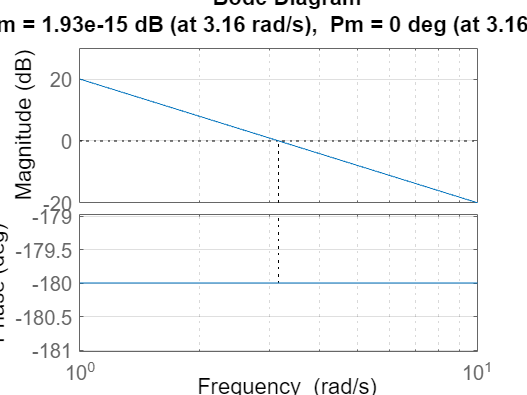

G = 10 / (s^2);   % type 2
margin(G), grid

### A lead compensator for a type-two system


$$\phi_{\text{pm}}\approx100\zeta=45\degree\\
\frac{\alpha-1}{\alpha+1}=\sin\phi_m=\sin45\degree\\
\Rightarrow\alpha\approx5.8\Rightarrow\text{choose }\alpha=6 \text{ (safety margin)}\\
10\log_{10}\alpha=7.78\text{dB}\Rightarrow\omega_m=4.95\text{ rad/s}\\
\Rightarrow p=\omega_m\sqrt\alpha,\ z=\frac{p}{\alpha}$$


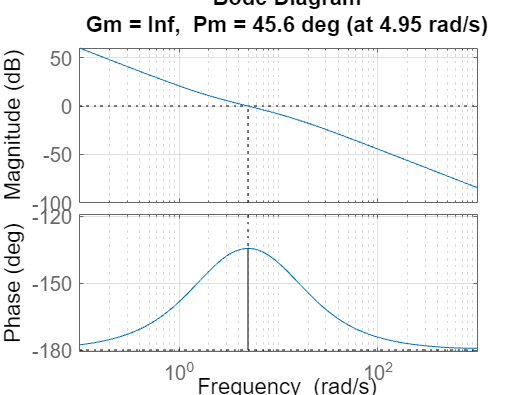

pzratio = 6;
omega_m = 4.95;
p = omega_m * sqrt(pzratio);
z = p / pzratio;
K = pzratio;
G_C = K * (s + z) / (s + p);
L = G_C * G;
T = feedback(L, 1);
margin(L), grid

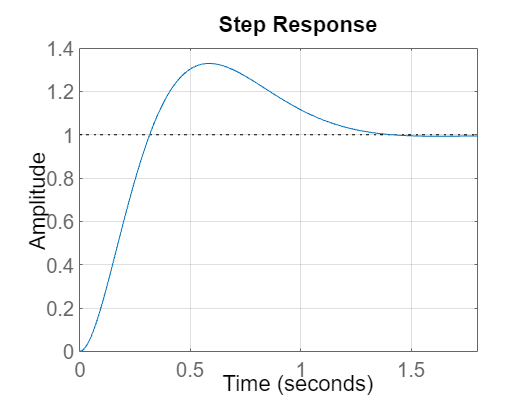

step(T), grid

stepinfo(T)

ans = struct with fields:
         RiseTime: 0.2188
    TransientTime: 1.2657
     SettlingTime: 1.2657
      SettlingMin: 0.9377
      SettlingMax: 1.3289
        Overshoot: 32.8881
       Undershoot: 0
             Peak: 1.3289
         PeakTime: 0.5908


damp(T)

                                                                       
         Pole              Damping       Frequency      Time Constant  
                                       (rad/seconds)      (seconds)    
                                                                       
 -3.59e+00 + 3.41e+00i     7.25e-01       4.95e+00         2.79e-01    
 -3.59e+00 - 3.41e+00i     7.25e-01       4.95e+00         2.79e-01    
 -4.95e+00                 1.00e+00       4.95e+00         2.02e-01    
